# DO Worked Example 

This example is provided by Kristen Fogaren (fogaren@bc.edu) on May 23, 2022. Thanks to Craig Reisin for providing the code to directly pull data from THREDDS server. 

*Note: users will also need download and add *[*Gibbs Sea Water Package*](https://www.teos-10.org/software.htm)* to path *

#### Overview

Here, we provide end-users with an example that uses discrete, Winkler-titrated oxygen measurements to correct for the storage drift and deployment drift of an OOI-provided Level 2 oxygen product to produce an oxygen product for scientific use. The Level 2 oxygen product is from an Aanderaa optode on the near-surface instrument frame on the Oregon Offshore Surface Mooring of the Coastal Endurance Array. 

*** Need to recalculate sensor burst averaging for comparison to Winkler Titrations when making gain correction. 

*** Could also add QARTOD investigation for CTD data and QC look at oxygen data

#### Pre-data download 

- [Quick look at oxygen data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#data/4) available on Data Explorer and saved as Data View 

- Target data is surface mooring so need to look at time period after the installation of anti-biofouling UV lights (April 2018)

- [Reference designator ](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103785/station/95/sensor/info?start=2019-04-05T20:51:40Z&end=2022-05-22T02:48:00Z&bin=days&leg_clim_upper_env=false&leg_clim_lower_env=false&leg_clim_mean=false&leg_clim_max=false&leg_clim_min=false&leg_qartod_1=false&leg_qartod_2=false&leg_qartod_3=false&leg_qartod_4=false&leg_qartod_9=false) = CE04OSSM-RID27-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered

- Also look at ancillary data from CTD (pressure, temperature, salinity) used to process oxygen data

- [Look at annotations and QARTOD tests](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103785/station/95/sensor/data?start=2019-04-05T20:51:40Z&end=2022-05-22T02:48:00Z&bin=days&leg_clim_upper_env=false&leg_clim_lower_env=false&leg_clim_mean=false&leg_clim_max=false&leg_clim_min=false) associated with oxygen data 

- No annotations other than UV light installation date and brief power outage

- Note, no QARTOD tests are implemented at this time for oxygen data streams 

- Identify deployments of interest as deployments 8 and 9 

#### Download and Plot Data

- Use local function to read in netCDFs directly from the THREDDS server and into data structures

- Reads in data for dissolved oxygen, salinity, temperature, pressure and accompanying QC or QARTOD tests 

% Read in data from OOI THREDDS server and display netCDF information 
deployment8 = pull_DO_Data_from_THREDDS('deployment0008');

Source:
           https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/ooigoldcopy/public/CE04OSSM-RID27-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered/deployment0008_CE04OSSM-RID27-03-CTDBPC000-recovered_host-ctdbp_cdef_dcl_instrument_recovered_20190420T201508.092000-20191021T190002.961000.nc#fillmismatch
Format:
           classic
Global Attributes:
           node                              = 'RID27'
           comment                           = ''
           publisher_email                   = ''
           sourceUrl                         = 'http://oceanobservatories.org/'
           collection_method                 = 'recovered_host'
           stream                            = 'ctdbp_cdef_dcl_instrument_recovered'
           featureType                       = 'point'
           creator_email                     = ''
           publisher_name                    = 'Ocean Observatories Initiative'
           date_modified                    

deployment9 = pull_DO_Data_from_THREDDS('deployment0009');

Source:
           https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/ooigoldcopy/public/CE04OSSM-RID27-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered/deployment0009_CE04OSSM-RID27-03-CTDBPC000-recovered_host-ctdbp_cdef_dcl_instrument_recovered_20191021T180010.284000-20200711T141505.596000.nc#fillmismatch
Format:
           classic
Global Attributes:
           node                              = 'RID27'
           comment                           = ''
           publisher_email                   = ''
           sourceUrl                         = 'http://oceanobservatories.org/'
           collection_method                 = 'recovered_host'
           stream                            = 'ctdbp_cdef_dcl_instrument_recovered'
           featureType                       = 'point'
           creator_email                     = ''
           publisher_name                    = 'Ocean Observatories Initiative'
           date_modified                    

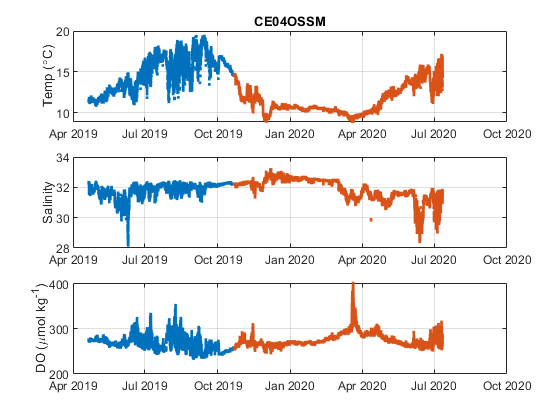

% Plot deployments
figure
ax1 = subplot(3,1,1);
plot(deployment8.CTDdt,deployment8.temp,'.')
hold on
plot(deployment9.CTDdt,deployment9.temp,'.')
ylabel('Temp (\circC)')
grid on
title('CE04OSSM')

ax2 = subplot(3,1,2);
plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
hold on
plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
ylabel('Salinity')
grid on

ax3 = subplot(3,1,3);
plot(deployment8.DOdt,deployment8.dissolved_oxygen,'.')
hold on
plot(deployment9.DOdt,deployment9.dissolved_oxygen,'.')
ylabel('DO (\mumol kg^-^1)')
grid on
linkaxes([ax3 ax2 ax1],'x')

- Noticable difference in downloaded dissolved oxygen data (consistent between deployments) and dissolved oxygen data on data explorer (offset between deployments).

- Answer from Chris Wingard: There was a bug in the system where values from two-point calibrations were not being used in processing of oxygen data. This has been updated in but it looks like Data Explorer has not updated the code it is using to reflect that change. He is submitting a helpdesk ticket. 5-23-2022

#### Compare to data from turn-around cruises

- Download discrete bottle summaries from Alfresco server for deployments 8 and 9

- Read in discrete bottle summaries and use local function (at end of script) to create water summary tables for site of interest 

- Plots show site of interest (CE04) and location of discrete samples for oxygen 

- Discrete water samples from Niskin bottles are measured for oxygen using Winkler titrations

- Temp and salinity data are from ship's CTD when Niksin bottles were fired 

- Plots showing discrete data with OOI datastreams 

% Set up workspace 
addpath('G:\My Drive\Matlab_work\Functions\GSW')

% All Endurance turn-around cruises during deployments 8 and 9
% Files pulled from Alfresco 
CE11 = readtable('Endurance-11_SKQ201910S_OC1905C_Discrete_Summary.xlsx','TextType','string');

CE12 = readtable('Endurance-12_SKQ201921S_Discrete_Summary.xlsx','TextType','string');

CE13 = readtable('Endurance-13_TN380_Discrete_Summary.xlsx','TextType','string');

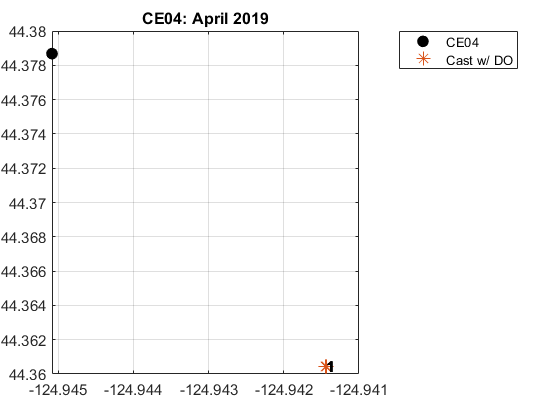


showplots = 1; % 1 to display plots of CTD cast locations 
location = 'CE04';

% Pull information for samples collected at Station == CE04
CE11CE04 = water_sample_table(CE11,location,showplots);  %( Cruise, Station, Plot)

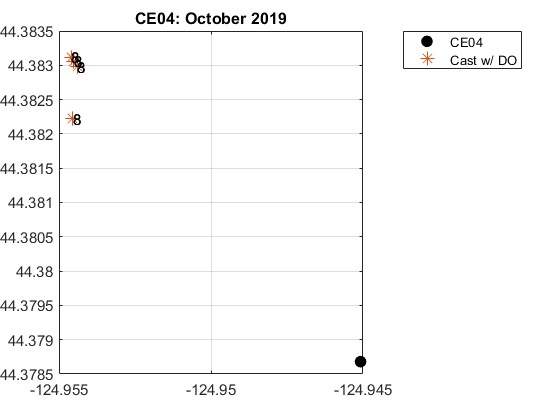

CE12CE04 = water_sample_table(CE12,location,showplots); 

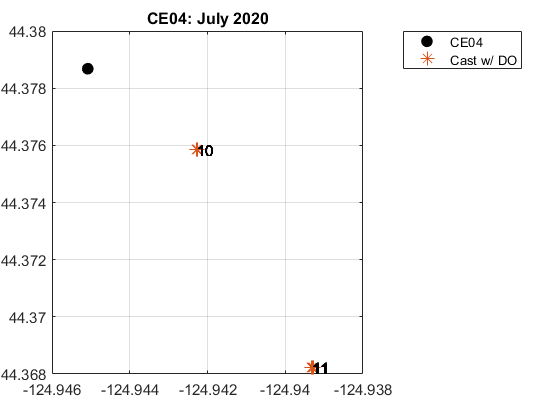

CE13CE04 = water_sample_table(CE13,location,showplots); 


% Create table for discrete sample information around CE04
CE_CE04 = [CE11CE04; CE12CE04; CE13CE04]

CE_CE04 = 34×15 table
       Cruise       Station    Cast    Niskin_BottlePosition    CTDLatitude_deg    CTDLongitude_deg    CTDPressure_db    CTDBottleClosureTime_UTC    CTDDepth_m    CTDTemperature1_degC    CTDSalinity1_psu    CTDOxygen_mL_L    DiscreteOxygen_mL_L    DiscreteOxygen_umolL    DiscreteOxygen_umolkg
    ____________    _______    ____    _____________________    _______________    ________________    ______________    ________________________    __________    ____________________    ________________    ______________    

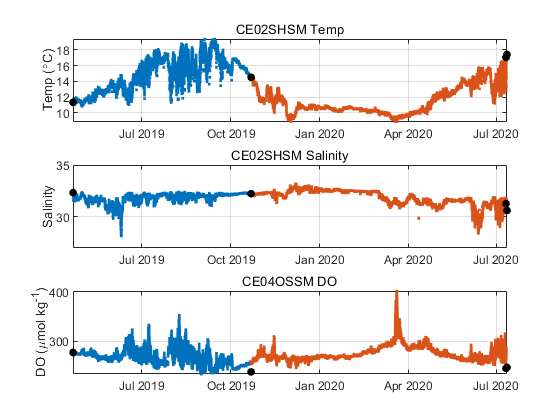

% Pulls out discrete temp/sal/DO data around depth of Near surface insturment frame at 7 m 
ind = find(CE_CE04.CTDDepth_m > 6 & CE_CE04.CTDDepth_m < 10); % Greater than 6 but less than 10 m 
ind = ind(1:end-2); % remove last two points during deployment 10
figure
ax1 = subplot(3,1,1);
plot(deployment8.CTDdt,deployment8.temp,'.')
hold on
plot(deployment9.CTDdt,deployment9.temp,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.CTDTemperature1_degC(ind),'.k','MarkerSize',20)
axis tight
grid on
ylabel('Temp (\circC)')
title('CE02SHSM Temp','fontweight','normal')

ax2 = subplot(3,1,2);
plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
hold on
plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.CTDSalinity1_psu(ind),'.k','MarkerSize',20)
axis tight
ylim([27 35])
grid on
ylabel('Salinity')
title('CE02SHSM Salinity','fontweight','normal')

ax3 = subplot(3,1,3);
plot(deployment8.DOdt,deployment8.dissolved_oxygen,'.')
hold on
plot(deployment9.DOdt,deployment9.dissolved_oxygen,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
axis tight 
grid on
ylabel('DO (\mumol kg^-^1)')
linkaxes([ax3 ax2 ax1],'x')
title('CE04OSSM DO','fontweight','normal')

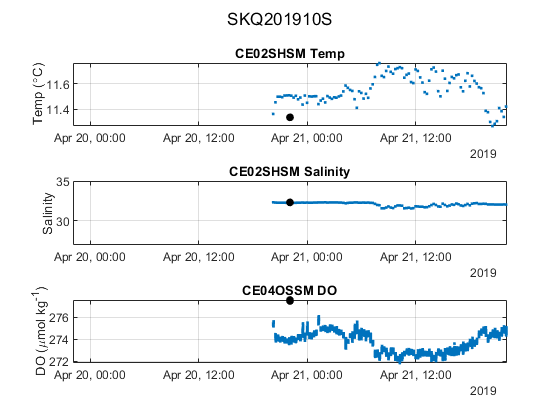

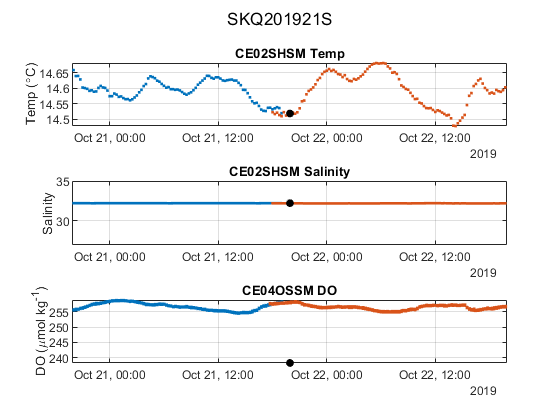

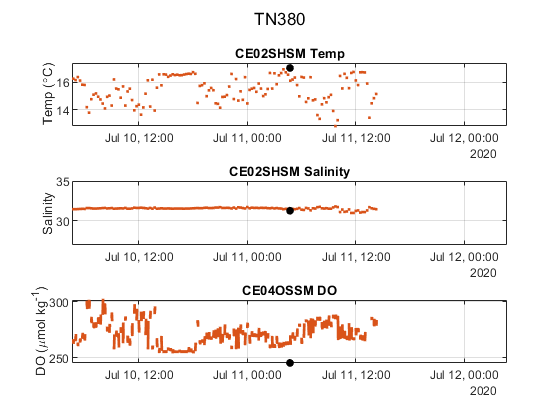

%% Take a closer look around turn-around cruises 

for j = 1:2:length(ind) % by 2 because duplicate Winklers and only need 1 bottle closing time 
    figure 
    ax1 = subplot(3,1,1);
    plot(deployment8.CTDdt,deployment8.temp,'.')
    hold on
    plot(deployment9.CTDdt,deployment9.temp,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.CTDTemperature1_degC(ind),'.k','MarkerSize',20)
    axis tight
    grid on
    ylabel('Temp (\circC)')
    title('CE02SHSM Temp')
    
    ax2 = subplot(3,1,2);
    plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
    hold on
    plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.CTDSalinity1_psu(ind),'.k','MarkerSize',20)
    axis tight
    ylim([27 35])
    grid on
    ylabel('Salinity')
    title('CE02SHSM Salinity')
    
    ax3 = subplot(3,1,3);
    plot(deployment8.DOdt,deployment8.dissolved_oxygen,'.')
    hold on
    plot(deployment9.DOdt,deployment9.dissolved_oxygen,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
    axis tight 
    grid on
    ylabel('DO (\mumol kg^-^1)')
    linkaxes([ax3 ax2 ax1],'x')
    xlim([CE_CE04.CTDBottleClosureTime_UTC(ind(j))-1 CE_CE04.CTDBottleClosureTime_UTC(ind(j))+1])
    title('CE04OSSM DO')
    sgtitle([CE_CE04.Cruise(ind(j))])
end

% Make table with just Winkler titrations of interest for depths and
% deployment times 
Winkler = CE_CE04(ind,:)

Winkler = 8×15 table
       Cruise       Station    Cast    Niskin_BottlePosition    CTDLatitude_deg    CTDLongitude_deg    CTDPressure_db    CTDBottleClosureTime_UTC    CTDDepth_m    CTDTemperature1_degC    CTDSalinity1_psu    CTDOxygen_mL_L    DiscreteOxygen_mL_L    DiscreteOxygen_umolL    DiscreteOxygen_umolkg
    ____________    _______    ____    _____________________    _______________    ________________    ______________    ________________________    __________    ____________________    ________________    ______________    <

cruise = unique(Winkler.Cruise) % Find unique cruise names 

cruise = 3×1 string array
    "SKQ201910S"
    "SKQ201921S"
    "TN380"


Wink_time = unique(Winkler.CTDBottleClosureTime_UTC)

Wink_time = 4×1 datetime array
   20-Apr-2019 22:06:37
   21-Oct-2019 19:56:16
   11-Jul-2020 04:43:16
   12-Jul-2020 04:56:01



Wink_Deploy8_start = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(1))])

Wink_Deploy8_start = 277.5179

Wink_Deploy8_end = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(2))])

Wink_Deploy8_end = 238.2993

Wink_Deploy9_start = Wink_Deploy8_end

Wink_Deploy9_start = 238.2993

Wink_Deploy9_end = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(3))])

Wink_Deploy9_end = 246.5103


sensorDO_Deploy8_start = deployment8.dissolved_oxygen(find(deployment8.DOdt > Wink_time(1),1))

sensorDO_Deploy8_start = 273.6999

sensorDO_Deploy9_start = deployment9.dissolved_oxygen(find(deployment9.DOdt > Wink_time(2),1)) 

sensorDO_Deploy9_start = 258.0572


% Should change to some type of burst averaging for sensor data 
gain8 = Wink_Deploy8_start/sensorDO_Deploy8_start

gain8 = 1.0139

gain9 = Wink_Deploy9_start/sensorDO_Deploy9_start

gain9 = 0.9234


% Adjust deployments for storage gain 
deploy8gain = deployment8.dissolved_oxygen*gain8;
deploy9gain = deployment9.dissolved_oxygen*gain9;

% Calculate in situ drift 
x8 = [Wink_time(1); Wink_time(2)]; 
y8 = [1; Wink_Deploy8_end/(deploy8gain(end))]; % in situ adjustment 1 to Winkler/sensor(already adjusted for gain)

deploy8drift = interp1(x8,y8,deployment8.DOdt); % Interp in situ drift correction for deployment 8 times 

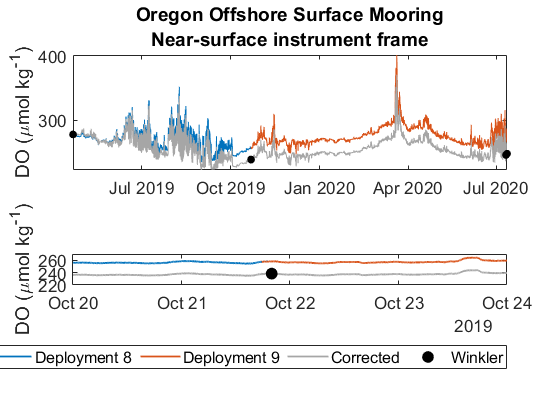

blue = [0     0.44706     0.74118];
red = [0.85098     0.32549    0.098039];
grey = [0.65098     0.65098     0.65098];

figure
subplot(2,1,1)
f = gca;
plot(deployment8.DOdt,movmean(deployment8.dissolved_oxygen,30),'Color',blue)
hold on
plot(deployment9.DOdt,movmean(deployment9.dissolved_oxygen,30),'Color',red)
plot(deployment8.DOdt,movmean(deploy8gain.*deploy8drift,30),'Color',grey)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
plot(deployment9.DOdt,movmean(deploy9gain,30),'Color',grey)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
axis tight 
f.FontSize =13; 
ylabel('DO (\mumol kg^-^1)')
title({['Oregon Offshore Surface Mooring'] 'Near-surface instrument frame'})

subplot(2,1,2)
f = gca;
plot(deployment8.DOdt,movmean(deployment8.dissolved_oxygen,30),'Color',blue,'Linewidth',1.25)
hold on
plot(deployment9.DOdt,movmean(deployment9.dissolved_oxygen,30),'Color',red,'Linewidth',1.25)
plot(deployment8.DOdt,movmean(deploy8gain.*deploy8drift,30),'Color',grey,'Linewidth',1.25)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',30)
plot(deployment9.DOdt,movmean(deploy9gain,30),'Color',grey,'Linewidth',1.25)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',30)
ylim([220 270]) 
xlim([datetime(2019,10,20,'TimeZone','UTC') datetime(2019,10,24,'TimeZone','UTC')])
f.FontSize =13; 
ylabel('DO (\mumol kg^-^1)')
legend('Deployment 8','Deployment 9','Corrected','Winkler','Location','southoutside',"Orientation",'horizontal')

function deployment = pull_DO_Data_from_THREDDS(deploy_num)
%   deploy_num = 'deployment0012' % string of deployment you want 
options = weboptions('Timeout', 600);

site = 'CE04OSSM-RID27-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered';
base_catalog_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/';

catalog = webread(strcat(base_catalog_url,site,'/catalog.html'),options);
nclist = regexp(catalog,'<a href=''([^>]+.nc)''>','tokens');
base_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/';

[~, ind] = find(contains(string(nclist),deploy_num) == 1);
    CTDind = ind(1); % CTD listed first
    DOSTAind = ind(2); % DOSTA listed second 

% For first file : CTD
CTD_url_thredds = nclist{1,CTDind}{1,1}; 
CTD_url_thredds = strcat(base_url,CTD_url_thredds(22:end),'#fillmismatch');
ncdisp(CTD_url_thredds) % Displays all info for variables in netCDF

% For second file: DOSTA
DOSTA_url_thredds = nclist{1,DOSTAind}{1,1}; 
DOSTA_url_thredds = strcat(base_url,DOSTA_url_thredds(22:end),'#fillmismatch');
ncdisp(DOSTA_url_thredds) % Displays all info for variables in netCDF

time = ncread(CTD_url_thredds,'time');
deployment.CTDdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
deployment.CTDdt = datetime(deployment.CTDdn,'ConvertFrom','datenum','TimeZone','UTC'); clear time
deployment.pressure_qartod_executed = ncread(CTD_url_thredds,'pressure_qartod_executed');
deployment.pressure_qartod_results = ncread(CTD_url_thredds,'pressure_qartod_results');
deployment.pressure = ncread(CTD_url_thredds,'pressure');
deployment.temp_qartod_executed = ncread(CTD_url_thredds,'temp_qartod_executed');
deployment.temp_qartod_results = ncread(CTD_url_thredds,'temp_qartod_results');
deployment.temp = ncread(CTD_url_thredds,'temp');
deployment.practical_salinity = ncread(CTD_url_thredds,'practical_salinity');
deployment.practical_salinity_qartod_executed = ncread(CTD_url_thredds,'practical_salinity_qartod_executed');
deployment.practical_salinity_qartod_results = ncread(CTD_url_thredds,'practical_salinity_qartod_results');
deployment.depth = ncread(CTD_url_thredds,'depth');
deployment.deployment = ncread(CTD_url_thredds,'deployment');

time = ncread(DOSTA_url_thredds,'time');
deployment.DOdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
deployment.DOdt = datetime(deployment.DOdn,'ConvertFrom','datenum','TimeZone','UTC'); clear time
deployment.dissolved_oxygen_qc_executed = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_executed');
deployment.dissolved_oxygen_qc_results = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_results');
deployment.dissolved_oxygen = ncread(DOSTA_url_thredds,'dissolved_oxygen');
deployment.lat = ncreadatt(DOSTA_url_thredds,'/','lat');
deployment.lon = ncreadatt(DOSTA_url_thredds,'/','lon');

end

function [DS] = water_sample_table(cruise,Station,showplots) 
DS = table(cruise.Cruise(cruise.Station == Station), cruise.Station(cruise.Station == Station), cruise.Cast(cruise.Station == Station), cruise.Niskin_BottlePosition(cruise.Station == Station),...
    cruise.CTDLatitude_deg_(cruise.Station == Station),cruise.CTDLongitude_deg_(cruise.Station == Station),cruise.CTDPressure_db_(cruise.Station == Station),...
    cruise.CTDBottleClosureTime_UTC_(cruise.Station == Station),cruise.CTDDepth_m_(cruise.Station == Station), cruise.CTDTemperature1_degC_(cruise.Station == Station),...
    cruise.CTDSalinity1_psu_(cruise.Station == Station), cruise.CTDOxygen_mL_L_(cruise.Station == Station), double(cruise.DiscreteOxygen_mL_L_(cruise.Station == Station)),...
    'VariableNames',{'Cruise','Station','Cast','Niskin_BottlePosition','CTDLatitude_deg','CTDLongitude_deg','CTDPressure_db','CTDBottleClosureTime_UTC',...
    'CTDDepth_m','CTDTemperature1_degC','CTDSalinity1_psu','CTDOxygen_mL_L','DiscreteOxygen_mL_L'});

DS.CTDBottleClosureTime_UTC = datetime(DS.CTDBottleClosureTime_UTC,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSZ','TimeZone','UTC');

DS.DiscreteOxygen_mL_L(DS.DiscreteOxygen_mL_L == -9999999) = NaN; % Replaces flag for missing data with NaN
DS.DiscreteOxygen_umolL = double(DS.DiscreteOxygen_mL_L)*44.661; % convert from ml/l to umol/l

% Code taken from OOI Github 
pref = 0; % Reference pressure (db)
SA = gsw_SA_from_SP(DS.CTDSalinity1_psu, DS.CTDPressure_db, DS.CTDLongitude_deg, DS.CTDLatitude_deg);
CT = gsw_CT_from_t(SA, DS.CTDTemperature1_degC, DS.CTDPressure_db);
pdens = gsw_rho(SA, CT, pref); % potential referenced to p=0

% Convert from volume to mass units:
DS.DiscreteOxygen_umolkg = 1000*DS.DiscreteOxygen_umolL./pdens;

% Location of Oregon Shelf Offshore Surface Mooring 
CE04OSSM = [44.37868, -124.94508]; % From OOI Website
dn = datenum(mean(DS.CTDBottleClosureTime_UTC,'omitnan')); % For Figure title 

    if showplots == 1
        figure
        plot(CE04OSSM(2),CE04OSSM(1),'.k','MarkerSize',30)
        hold on
        plot(DS.CTDLongitude_deg,DS.CTDLatitude_deg,'*','MarkerSize',10)
        title([Station ': ' datestr(dn,'mmmm yyyy')])
        grid on
        legend('CE04','Cast w/ DO','Location','northeastoutside')
        
        casts = unique(DS.Cast);
        for i = 1:length(casts)
            text(DS.CTDLongitude_deg(DS.Cast == casts(i)),DS.CTDLatitude_deg(DS.Cast == casts(i)),{casts(i)})
        end
    end
end
